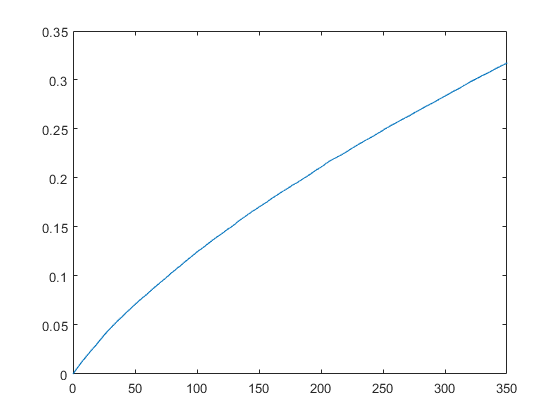

clear all
close all
clc
load dreitankErgebnisse.mat


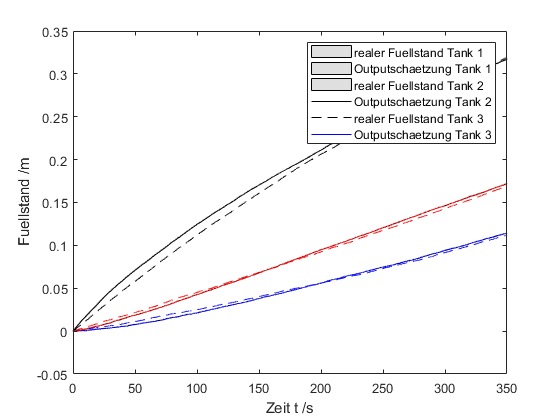

figure(1)
f1 = [x_out(1,:)+2*sqrt(s2_out(1,:)), flip(x_out(1,:)-2*sqrt(s2_out(1,:)),2)];
f2 = [x_out(2,:)+2*sqrt(s2_out(2,:)), flip(x_out(2,:)-2*sqrt(s2_out(2,:)),2)];
f3 = [x_out(3,:)+2*sqrt(s2_out(3,:)), flip(x_out(3,:)-2*sqrt(s2_out(3,:)),2)];
fill([n, flip(n,2)], f1, [7 7 7]/8)
hold on; 
fill([n, flip(n,2)], f2, [7 7 7]/8)
fill([n, flip(n,2)], f3, [7 7 7]/8)

plot(n, x_out(1,:), 'k', n, x_est_out(1,:), '--k', n, x_out(2,:), 'b', n, x_est_out(2,:), '--b', n, x_out(3,:), 'r', n, x_est_out(3,:),'--r');
legend('realer Fuellstand Tank 1', 'Outputschaetzung Tank 1', 'realer Fuellstand Tank 2', 'Outputschaetzung Tank 2', 'realer Fuellstand Tank 3', 'Outputschaetzung Tank 3');
xlabel('Zeit t /s')
ylabel('Fuellstand /m')
hold off;

sum((x_out(1,:)-x_est_out(1,:)).^2) / length(x_out(1,:))

ans = 6.2582e-05

error =(x_out(1,:)-x_est_out(1,:));
var(x_out(1,:),x_est_out(1,:))

ans = 0.0045

immse(x_out(2,:),x_est_out(2,:))

ans = 6.5786e-06

immse(x_out(3,:),x_est_out(3,:))

ans = 7.9898e-06